use8Bit = false;
%#ok<*UNRCH>

[S, P] = Speed_Motion_OKN();
disp(S)

             verbose: 0
             use8Bit: 0
       TimeSensitive: [1 2 3 4 5 6 7]
            DataPixx: 0
          rewardType: "None"
      eyetrackerType: "Mouse"
            DummyEye: 1
         DummyScreen: 1
             EyeDump: 0
               gamma: 2.2000
            bgColour: 0.5000
             monitor: 'Laptop'
        screenNumber: 1
           frameRate: 60
          screenRect: [0 0 960 540]
         screenWidth: 15
           centerPix: [480 270]
         guiLocation: [1000 100 890 660]
      screenDistance: 70
           pixPerDeg: 78.4890
    MarmoViewVersion: '5'
              finish: 200
            protocol: 'Speed_Motion_OKN'
      protocol_class: 'protocols.PR_Speed_Motion_OKN'
       protocolTitle: 'Foraging with back mapping'
        rewardNumber: 'Number of juice pulses to deliver:'
      CycleBackImage: 'If def, backimage every # trials:'
            trialdur: 'Trial Duration (s):'
       rewardGapTime: 'Drop of juice every number seconds'
              

A = struct();
A = marmoview.openScreen(S, A);

Unrecognized field name "bgColour".

Error in marmoview.openScreen (line 42)
            0, S.bgColour, S.screenRect);
            ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

rPix = floor(obj.radius);  % Radius
dPix = 2 * rPix + 1;  % Diameter

% Create the Gaussian envelope
[X, Y] = meshgrid(-rPix:rPix);  
sigma = dPix / 8;
e1 = exp(-.5*(X.^2 + Y.^2) / sigma^2);

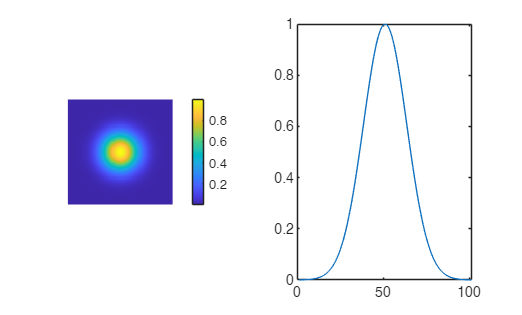


figure(); 
subplot(121); imagesc(e1); axis equal tight off; colorbar();
subplot(122); plot(e1(51,:));

if obj.pixperdeg > 0
    maxRadians = 2 * pi * obj.cpd / obj.pixperdeg;
else
    maxRadians = 2 * pi * obj.cpd / 20;
end
maxRadians

maxRadians = 0.6283

theta = obj.phase * pi/180;
tic
s1 = cos( cos(obj.orientation*pi/180) * (maxRadians*Y) + ...
    sin(obj.orientation*pi/180) * (maxRadians*X) + theta);
toc

Elapsed time is 0.004159 seconds.


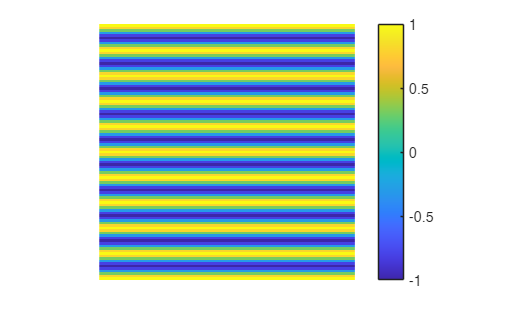

figure(); imagesc(s1); axis equal tight off; colorbar();